clear

## Esercizio 1

Vogliamo mostrare come il magnete ritorna sempre alla posizione di equilibrio, a prescindere  dal valore di z(0).

Infatti la sua funzione di trasferimento è stabile, tuttavia il sistema impiega un lungo periodo di tempo per assestarsi alla posizione di equilibrio, per velocizzare le simulazioni aumenteremo il valore di `d` a `0.1`.

Il valore di convergenza al variare di z(0) è il valore ottenuto dopo 10 secondi di simulazione.

Vediamo il grafico in un particolare caso, dove `z(0)=0.35` e `d=0.1`

% Load parameters
load_parameters;
params.d = 0.1;

% Define the simulation time step
dt = 0.1;

tic

% Initialize variables for control loop
z0 = params.z_eq + 0.05; % Initial condition for magnet position

% Pre-allocate arrays to store simulation results
tf = 10.0;
tSpan = linspace(0, tf, tf/dt); % Time vector with sampling rate of 100Hz
z_ref = params.z_eq + 0.3; % Reference position for control
dz_ref = 0; % Reference velocity for control
num_steps = tf / dt;
t_result = zeros(num_steps, 1); % Time vector to store simulation time
x_result = zeros(num_steps, 2); % Matrix to store magnet position and velocity

% Control loop
t_current = 0.0;
x_current = [z0; 0]; % Initial state vector [position; velocity]
for i = 1:num_steps
    % Calculate error
    error = z_ref - x_current(1);
    
    % Calculate control signal (not implemented yet, set to zero)
    u = 0;

    % Store current time and state
    t_result(i) = t_current;
    x_result(i, :) = x_current;
    
    % Update state using ODE integration
    [t_out, x_out] = ode15s(@(t, x) magnet_levitation_ode(x(1), x(2), u, params), [t_current t_current + dt], x_current);
    
    % Update current time and state for next iteration
    t_current = t_out(end);
    x_current = x_out(end, :);

end % for i = 1:num_steps

fprintf('Simulation time: %.2fs\n', toc) % toc stops the clock for computing the simulation time

Simulation time: 0.04s


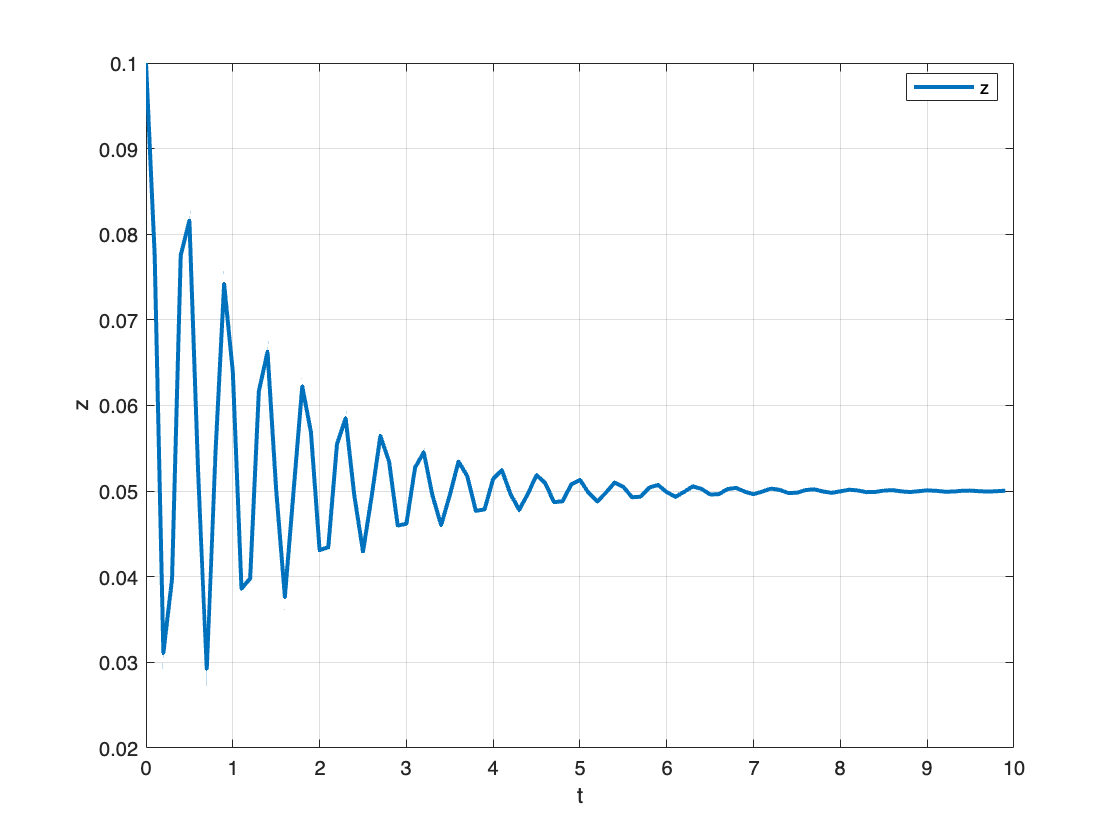

figure;
clf; grid on; hold on; box on;

plot(t_result, x_result(:, 1),'linewidth',2)
legend({'z'},'location','best')
xlabel('t')
ylabel('z')

Vediamo ora una tabella che mostra come al variare di `z(0)` il valore di convergenza rimane `0.05`

% Load parameters
load_parameters;

% Define the simulation time step
dt = 0.1;

% Start recording how much time the simulation takes
tic

reps = 20;

res_value = zeros(reps, 1);
z0_value = zeros(reps, 1);

for j = 1:reps
    z0 = params.z_eq + j; % Initial condition for magnet position
    z0_value(j) = z0;
    
    % Pre-allocate arrays to store simulation results
    tf = 10.0;
    num_steps = tf / dt;
    
    % Control loop
    t_current = 0.0;
    for i = 1:num_steps
        % Calculate error
        error = z_ref - x_current(1);
        
        % Calculate control signal (not implemented yet, set to zero)
        u = 0;
        
        % Update state using ODE integration
        [t_out, x_out] = ode15s(@(t, x) magnet_levitation_ode(x(1), x(2), u, params), [t_current t_current + dt], x_current);
        
        % Update current time and state for next iteration
        t_current = t_out(end);
        x_current = x_out(end, :);
    
    end % for i = 1:num_steps
    res_value(j) = x_out(end,1);
end

fprintf('Simulation time: %.2fs\n', toc) % toc stops the clock for computing the simulation time

Simulation time: 0.18s


T = table(z0_value, res_value);
disp(T);

    z0_value    res_value
    ________    _________

      1.05      0.049988 
      2.05      0.049999 
      3.05          0.05 
      4.05          0.05 
      5.05          0.05 
      6.05          0.05 
      7.05          0.05 
      8.05          0.05 
      9.05          0.05 
     10.05          0.05 
     11.05          0.05 
     12.05          0.05 
     13.05          0.05 
     14.05          0.05 
     15.05          0.05 
     16.05          0.05 
     17.05          0.05 
     18.05          0.05 
     19.05          0.05 
     20.05          0.05 



## Esercizio 2

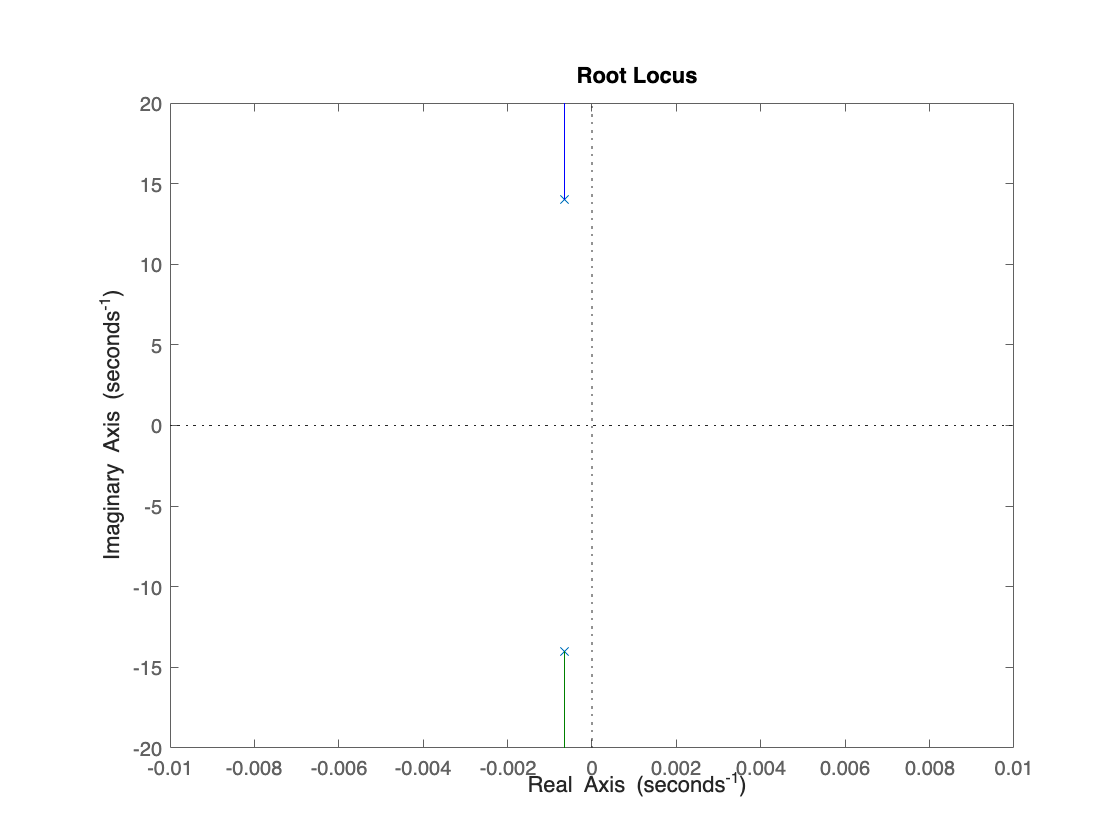

clear tf;
figure;
s = tf('s');
sys = (params.b_s)/(params.z_eq * params.m * s^2 + params.z_eq * params.d * s + params.m * params.g);
rlocus(sys)
axis([-0.01 0.01 -20 20])